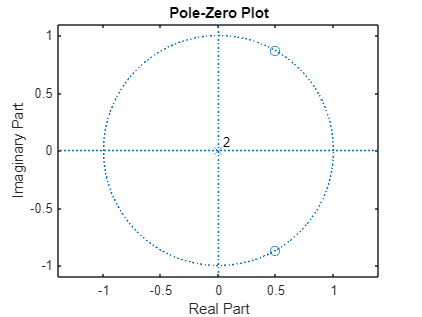

% Define the coefficients of the difference equation
b = [1/3, -1/3, 1/3];
a = [1, 0, 0]; % Denominator coefficients

% Determine H(z) from the difference equation coefficients
Hz = tf(b, a, 1); % Create transfer function

% Determine the impulse response h[n] using MATLAB
h = impz(b, a); % Get impulse response

% Zero-pad the shorter vector to match lengths
if length(b) < length(a)
    b = [b, zeros(1, length(a) - length(b))];
elseif length(a) < length(b)
    a = [a, zeros(1, length(b) - length(a))];
end

% Get the pole-zero diagram
[z, p] = tf2zp(b, a); % Get zeros and poles
figure;
zplane(z, p); % Plot pole-zero diagram


% Comment about the stability of the system
if all(abs(p) < 1) % Check if all poles are inside the unit circle
    disp('The system is stable.');
else
    disp('The system is unstable.');
end

The system is stable.
